### Growth in 10% Compost Wastewater

This experiment measured the growth of R. Palustris in 10% compost wastewater in 8 test tubes labelled A through H. There is no difference between samples. Data collection began on 03/08. Optical density was measured approximately every 12 hours until growth plateaued on [].

clear
clf

data = readmatrix('rpalus_10percent_03112023.csv');
num_datapoints = (length(data));

% label data from csv
time = data(:, 1) / 60;     % hours
A = data(:, 2); % optical density
B = data(:, 3); % optical density
C = data(:, 4); % optical density
D = data(:, 5); % optical density
E = data(:, 6); % optical density
F = data(:, 7); % optical density
G = data(:, 8); % optical density
H = data(:, 9); % optical density

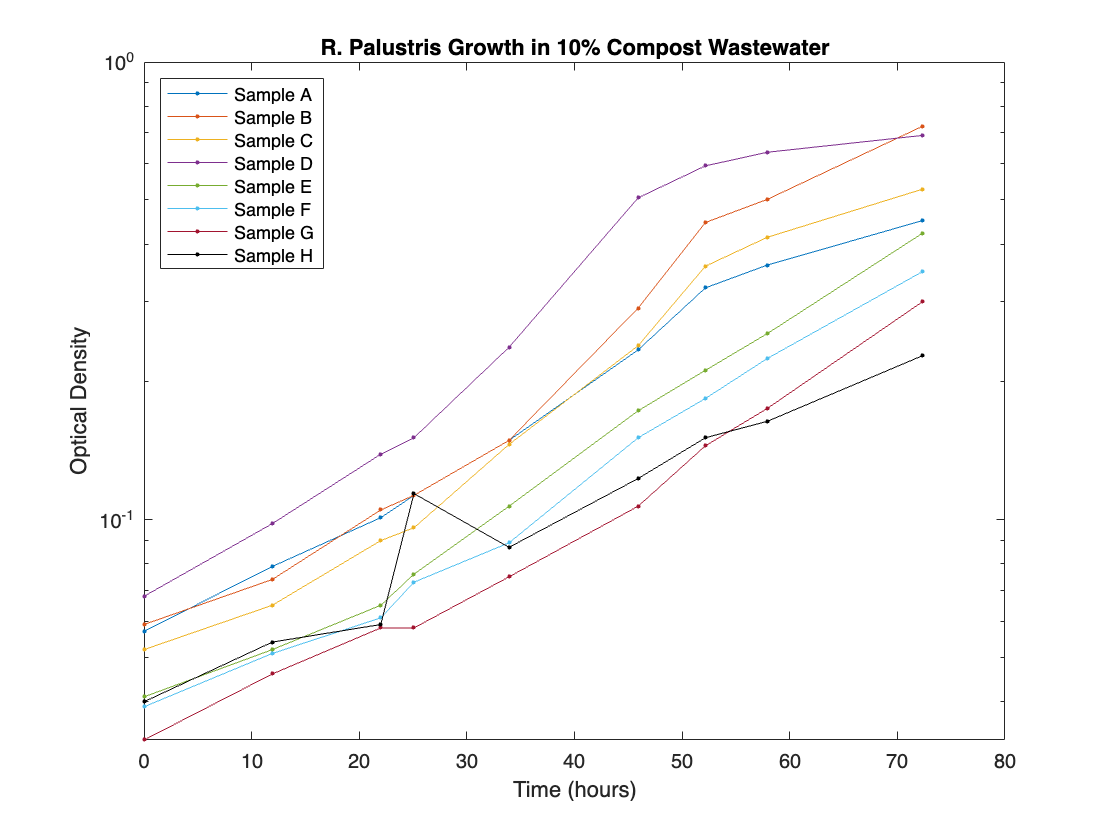

figure
semilogy(time, A, '.    -');
hold on
semilogy(time, B, '.-');
semilogy(time, C, '.-');
semilogy(time, D, '.-');
semilogy(time, E, '.-');
semilogy(time, F, '.-');
semilogy(time, G, '.-');
semilogy(time, H, 'k.-');

title("R. Palustris Growth in 10% Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample A","Sample B","Sample C","Sample D", ...
        "Sample E","Sample F","Sample G", "Sample H", ...
        "Location", "northwest")
hold off

## Fitting & Analysis

### Sample A

We isolated the exponential section of the sample A curve, which happens between the 1st and 6th data point.

isolate_A = 1:6;

We can now use the `fit` function to get an exponential fit.

[fitobjectA, gofA] = fit_data(A, isolate_A, time)

fitobjectA =      General model Exp1:
     fitobjectA(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.05034  (0.04261, 0.05806)
       b =     0.03317  (0.02908, 0.03726)

gofA = struct with fields:
           sse: 1.3521e-04
       rsquare: 0.9933
           dfe: 4
    adjrsquare: 0.9916
          rmse: 0.0058


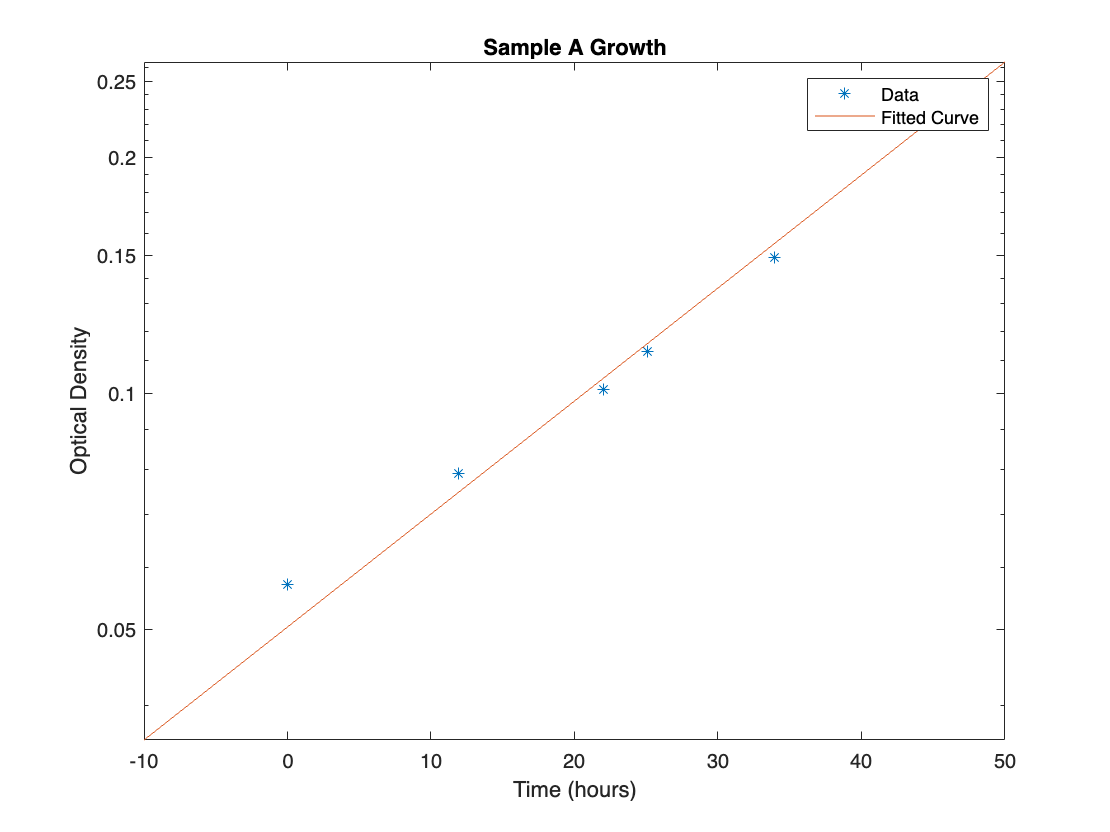

title("Sample A Growth")

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 05034*e^{0\ldotp 03317x}$$


with an r squared value of 0.9933. 

### Sample X

We isolated the exponential section of the sample A curve, which happens between the 1st and 6th data point.

%isolate_x = ;

We can now use the `fit` function to get an exponential fit.

%[fitobjectX, gofX] = fit_data(X, isolate_X, time)

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=*e^x$$


with an r squared value of. 